% Tasks:

% 1. Dataset collection 🎑🏞️
% 2. ⁠Animal identification 🆔 
% 3. ⁠Color detection 🔴🟣🔵🟢
% 4. ⁠Image labels 🏷️

% https://www.mathworks.com/matlabcentral/answers/1720245-hi-all-how-to-create-image-datasets-i-need-them-to-train-neural-networks-i-have-about-15-to-20

dataDir = '/cats';
% use image folder to get dataset
imds = imageDatastore(dataDir,'IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');
% use Alexnet to get cnn model
alex_net = alexnet;
class_number = length(unique(imds.Labels));
alex_net_share = alex_net.Layers(1:end-3);
alex_net_add = [
    fullyConnectedLayer(class_number,'Name','fc8','WeightLearnRateFactor',10, 'BiasLearnRateFactor',20)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classification')
    ];
layers_1 = [alex_net_share
    alex_net_add];
% train
augimdsTrain = augmentedImageDatastore([227 227],imdsTrain);
augimdsValidation = augmentedImageDatastore([227 227],imdsValidation);
miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false);
trainedNet = trainNetwork(augimdsTrain,layers_1,options);
% test
[YPred,probs] = classify(trainedNet,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.8246

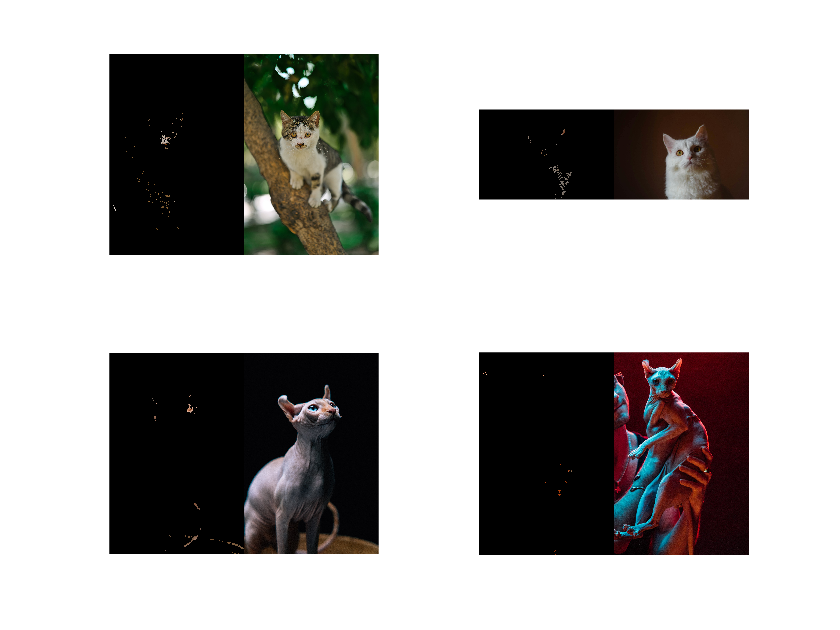

im = 6000×4000×3 uint8 array
im(:,:,1) =

     2     2     2     1     2     2     3     3     2     2     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     2     2     2     3     4     4     4     4     4     4     6     6    10    10     9     9     9     9     9     9    11    10     9     8     8     9    10    11     8     8     8     8     9     9     9    10    10    10    10    10     9     9     9     9    10    10    10    10    11    11    11    10    11    10    10    10    10    10    11    11     9     9    10    10    10    10    10    10    16    15    15    15    15    15    15    15    14    14    16    16    16    16    16    16    17    17    17    17    17    17    18    18    19    19    21    21    21    21    21    21    19    19    19    19    19    19    19    19    19    20    21    22    22    21    20    19    23    22    22    21    20    19    19    18    20    20    21    21    21    22    22    

path = '/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats'

ImOutFolder = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/catsDone"

file = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats/ctapplied1jpg"

im = 4000×6000×3 uint8 array
im(:,:,1) =

  Columns 1 through 5,461

    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18    18 

path = '/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats'

ImOutFolder = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/catsDone"

file = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats/ctapplied2jpg"

im = 6072×4048×3 uint8 array
im(:,:,1) =

     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     0     1     2     3     4     4     3     2     3     3     3     3     3     3     3     3     5     4     3     2     2     2     3     3     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     5     4     2     1     1     1     2     2     2     2     3     4     4     5     6     6     3     3     3     3     4     4     5     5     3     3     3     3     3     3     3     3     2     2     2     3     3     4     4     4     4     4     4     4     4     4     4     4     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     5     5     5     5     5     5     5     5     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3    

path = '/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats'

ImOutFolder = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/catsDone"

file = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats/ctapplied3jpg"

im = 3835×2557×3 uint8 array
im(:,:,1) =

    83    74    67    69    67    62    58    57    68    67    67    68    73    77    80    74    52    51    59    64    68    70    71    72    59    67    70    62    57    63    68    69    62    70    83    87    84    76    67    61    63    71    77    78    79    78    73    68    76    79    84    84    85    82    82    81    80    75    69    62    59    57    56    56    62    65    68    69    69    65    66    67    58    73    80    72    67    71    71    66    83    92    95    90    78    70    68    69    70    68    66    64    63    64    64    70    82    79    71    73    83    90    89    82    80    73    74    78    83    82    85    88    73    71    71    68    66    62    60    58    63    64    64    67    74    83    83    77    87    86    83    83    83    83    84    85    71    84    89    81    75    80    84    83    75    68    68    74    87    91    86    79    75    78    78    77    71    67    64    

path = '/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats'

ImOutFolder = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/catsDone"

file = "/Users/daniellegarsten/Documents/Documents - Danielle’s MacBook Air/FAU/COT 5930/cats/ctapplied4jpg"

% app
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");

    im = I
    path = dataDir
    mask=createMask(im);
    segmentedImg = im .* uint8(repmat(mask, [1, 1, size(im, 3)]));
    imgcombined= [segmentedImg,im];
    imshow(imgcombined)
    ImOutFolder = "/catsDone"
    ImFileOut=fullfile(ImOutFolder, strcat('CTApplied',int2str(i),'.jpg'));
    file =  path + "/ctapplied" + i + "jpg"
    imwrite(imgcombined, path + "/ctapplied" + i + ".jpg" );

end

function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 06-Feb-2024
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.049;
channel1Max = 0.092;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.082;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.441;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
